# Lab 4

## Problem 1

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays. Metadata is incorporated in the data file. 

### 1) Downloading, Importing, and Analyzing Data

Importing data...

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

The columns of my data are time, solar phase, earth longitude, and counts, respectively. 

*Separating each variable into its own column vector:*

time = mydata(:,1);
solphase = mydata(:,2);
earthlong = mydata(:,3);
counts = mydata(:,4);

#### *Basic Plots of Each Variable Versus Time:*

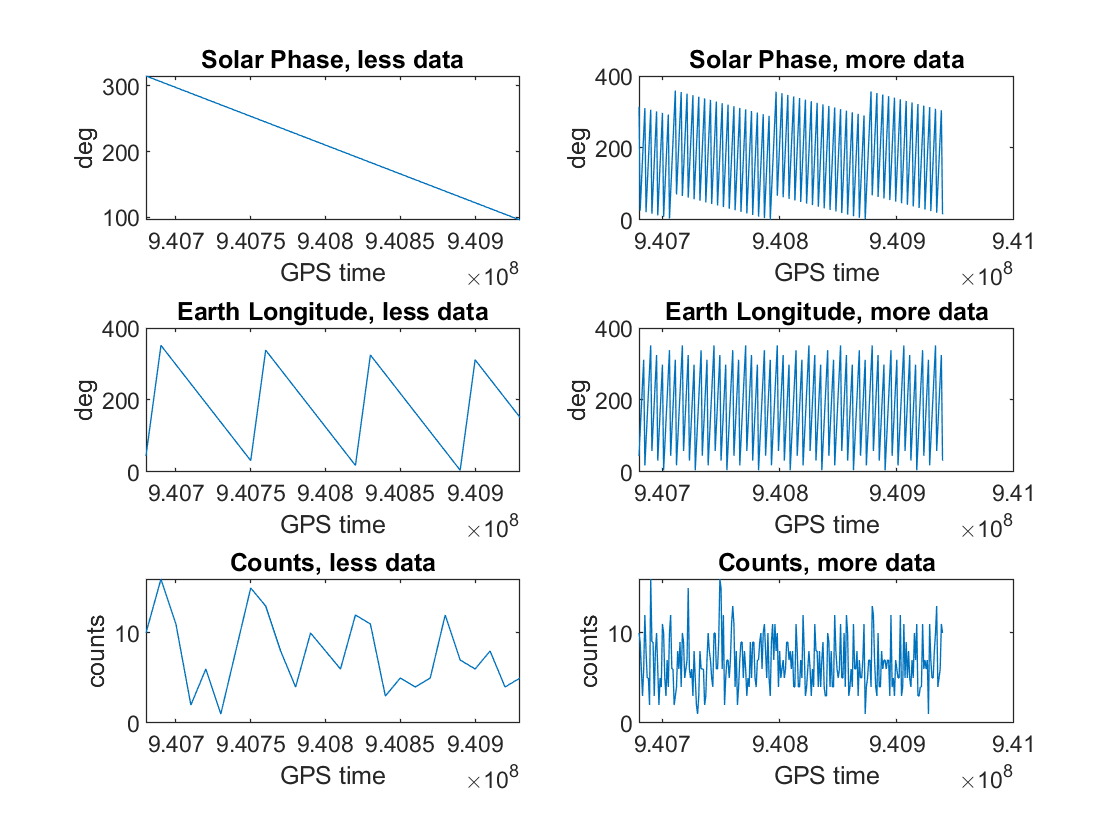

smallsp = (1:100000:2592001);
widesp = (1:10000:2592001);
subplot(3,2,1)
plot(time(smallsp),solphase(smallsp))
title('Solar Phase, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,2)
plot(time(widesp),solphase(widesp))
title('Solar Phase, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,3)
plot(time(smallsp),earthlong(smallsp))
title('Earth Longitude, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,4)
plot(time(widesp),earthlong(widesp))
title('Earth Longitude, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,5)
plot(time(smallsp),counts(smallsp))
title('Counts, less data')
xlabel('GPS time')
ylabel('counts')
subplot(3,2,6)
plot(time(widesp),counts(widesp))
title('Counts, more data')
xlabel('GPS time')
ylabel('counts')

*Observations:*

- Solar phase and Earth longitude graphs are uniform and appear to be periodic. 

- Counts vs. time graph is random. There doesn't appear to be a direct correlation between counts and time. 

- No obvious outliers looking at these graphs (though they don't contain all of the data). Taking a look at maxima and minima and comparing to these graphs will give a better understanding of outliers. 

*Maxima and minima: *

maxsp = max(solphase)

maxsp =      3.599999986496987e+02


minsp = min(solphase)

minsp =      6.994188879616559e-06


maxel = max(earthlong)

maxel =      3.599933333317458e+02


minel = min(earthlong)

minel =      0


maxc = max(counts)

maxc =     30


minc = min(counts)

minc =      0


Comparing these values to my graphs, it seems the solar phase has no outliers, since the maximum and minimum values are within the uniform periodic values seen in the "more data" plot. 

Similarly, Earth longitude's maximum and minimum values are consistent with its plot. 

The maximum for counts is more out there; however, 30 counts is feasible. It's not orders of magnitude above the other data points. From the "more data" plot, the counts values seem to hover around 6. For comparison, I'll check the average of all the counts data: 

avgcounts = mean(counts)

avgcounts =    7.097305243159520


n30 = find(counts>29);
num30 = length(n30)

num30 =      3


The average counts is about 7, so 30 is far above the average. Also, there are only 3 occurrences of 30 counts in the entire data set, so a measurement of 30 counts is far above average. 

p = num30/length(counts);
sigma = norminv(p)

sigma =   -5.172096906671110


The sigma of measuring 30 counts is above 5, so it is significant. However, there are only 3 such measurements out of millions, so they shouldn't influence my background. 

#### *Counts vs. Other Stuff (Histograms):*

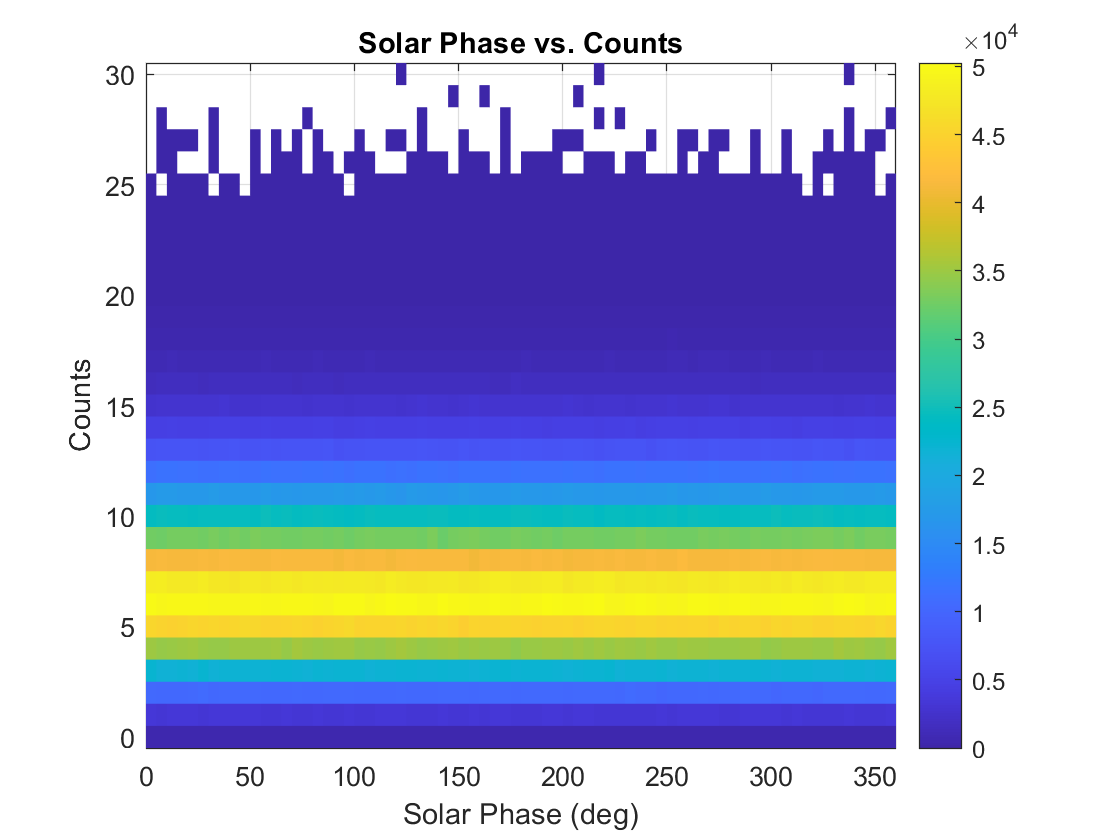

subplot(1,1,1)
histogram2(solphase,counts,'DisplayStyle','tile')
colorbar
title('Solar Phase vs. Counts')
xlabel('Solar Phase (deg)')
ylabel('Counts')

Counts and solar phase seem to be independent of each other. The graph shows a perfectly uniform gradient, so counts don't change at all with changes in solar phase. 

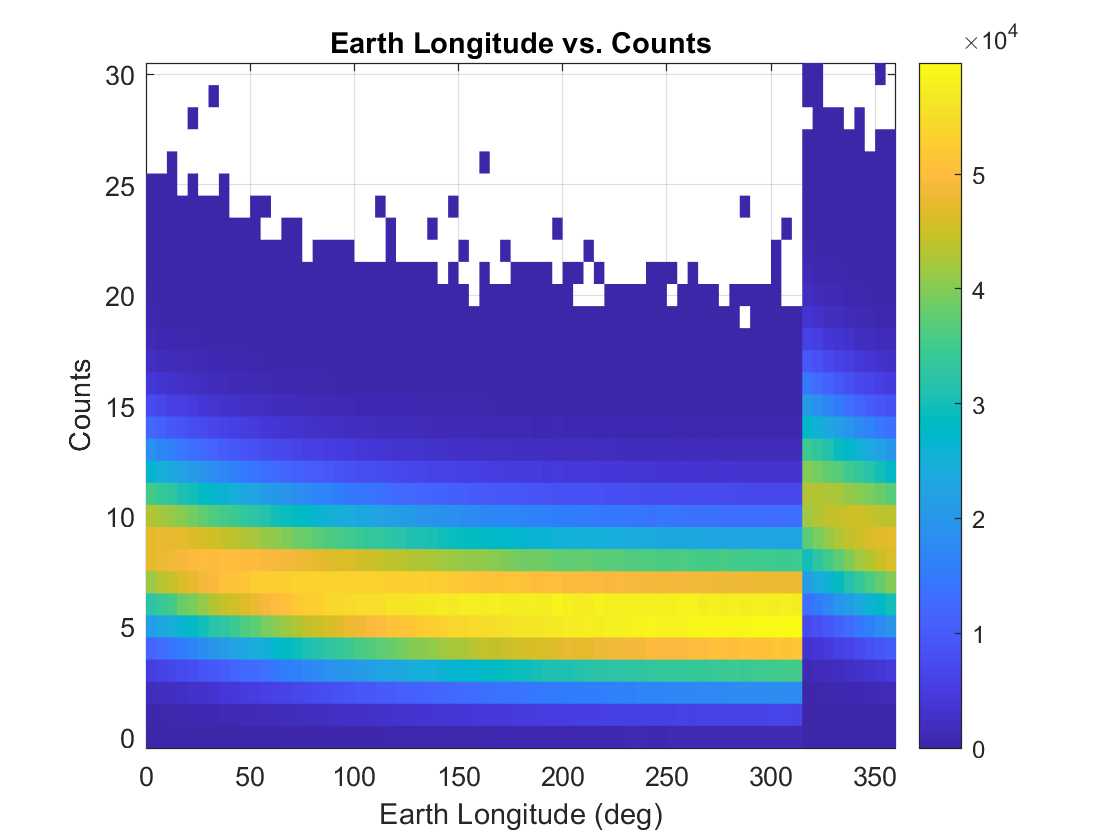

subplot(1,1,1)
histogram2(earthlong,counts,'DisplayStyle','tile')
colorbar
title('Earth Longitude vs. Counts')
xlabel('Earth Longitude (deg)')
ylabel('Counts')

There's a correlation between counts and Earth longitude. In the graph, there's a distinct jump around 315-325 degrees. Since the longitude appears to be periodic with time, the start of the 'period' may not be 0. Judging by the graph, it starts at that jump. Considering the > 320 region to the left of 0, there appears to be some form of decay, with a sharp decline early on that flattens out to a straight line. 

For our background, we should therefore consider how the distribution of counts changes within a period of Earth longitude data. 

*Histograms of counts:*

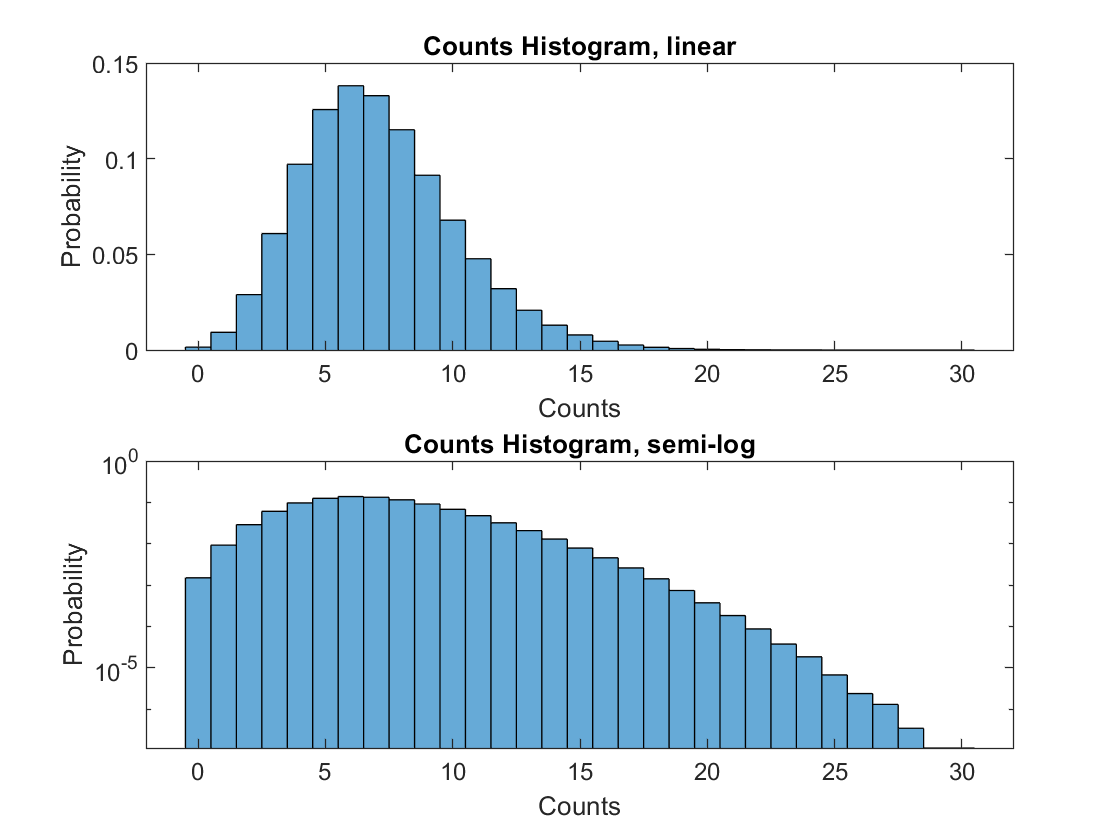

subplot(2,1,1)
histogram(counts,'Normalization','pdf')
title('Counts Histogram, linear')
xlabel('Counts')
ylabel('Probability')
subplot(2,1,2)
histogram(counts,'Normalization','pdf')
set(gca,'Yscale','log')
title('Counts Histogram, semi-log')
xlabel('Counts')
ylabel('Probability')


lambda = mean(counts);

Looking at these histograms, the distribution of counts looks like a Poisson distribution. I've assigned 'lambda' to the mean to use in generating a Poisson distribution for comparison.

*Overlay with Poisson:*

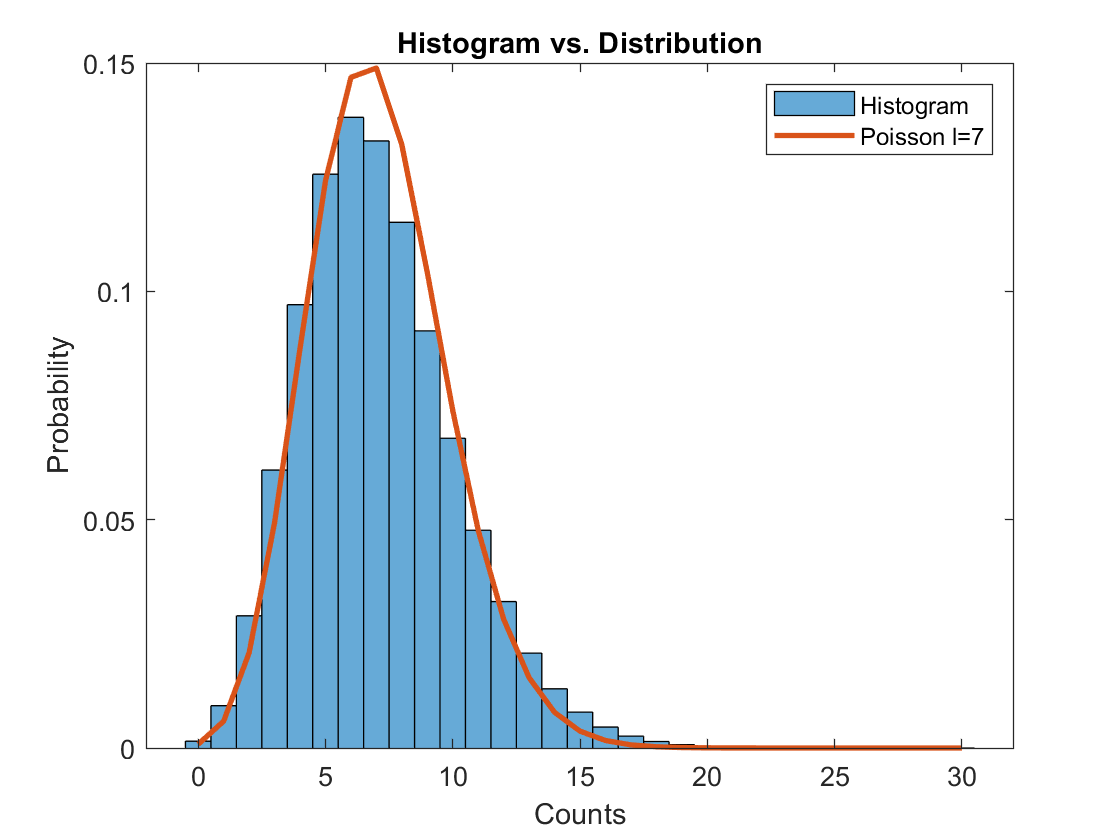

subplot(1,1,1)
histogram(counts,'Normalization','pdf')
title('Histogram vs. Distribution')
xlabel('Counts')
ylabel('Probability')
hold on
xes = 0:1:30;
pd = makedist('Poisson','lambda',lambda);
plot(xes,pdf(pd,xes),'LineWidth',2)
legend('Histogram','Poisson l=7')
hold off

The overlay matches the histogram fairly well, so I'm confident in using a Poisson distribution for my background. 

### 2) Non-Consistent Background: How Does it Change?

As seen in the histogram in section (1), the background (counts) changes with the value of Earth's longitude. 

Here I take the means of 10008 subsections of the data and plot their values versus the value of Earth longitude in each subsection. 

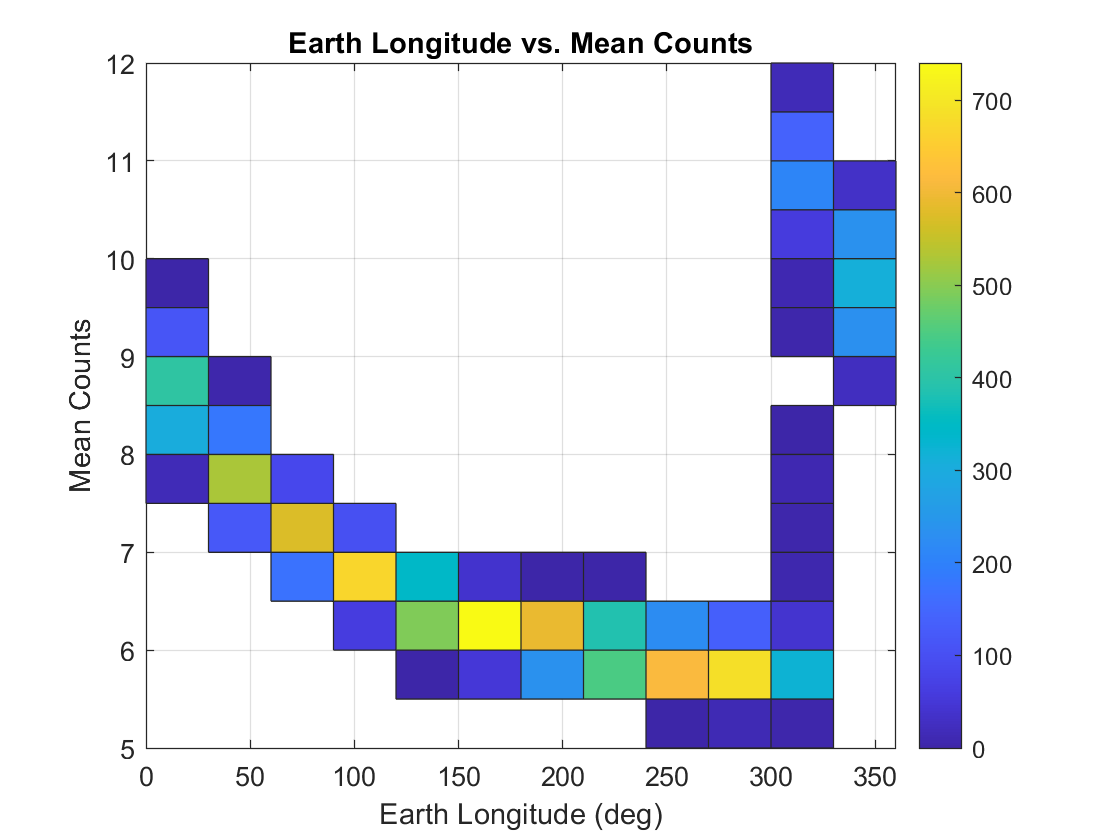

cmeans = zeros(10008,1);

for i = 0:10007
    cmeans(i+1,1) = mean(mydata((259*i+1):(259*(i+1)),4));
end

elpoints = mydata(1:259:2592001,3);

subplot(1,1,1)
histogram2(elpoints,cmeans,'DisplayStyle','tile')
colorbar
title('Earth Longitude vs. Mean Counts')
xlabel('Earth Longitude (deg)')
ylabel('Mean Counts')

*Observations:*

As expected, the means follow the same pattern as the counts versus Earth's longitude histogram in the previous section. From this, we can surmise that the number of counts is inversely proportional to the Earth longitude data over each period. Like before, the period starts around 330 degrees, or -30 degrees.

*How does the background change?*

The background Poisson distribution is dependent solely on its 'lambda' condition, which in this case is the average counts. The average counts drops over a period of Earth's longitude, implying that the background distribution shifts to the left during a single period. Given the decay-nature of the relationship between average counts and longitude, the shift is most dramatic at the start of the period and changes less as the period continues.

### 3) Background Model (with Time Dependence!) 

Earth longitude is a periodic function with time. This means that the background distribution will also change periodically with the longitude. 

*Finding the length of the period:*

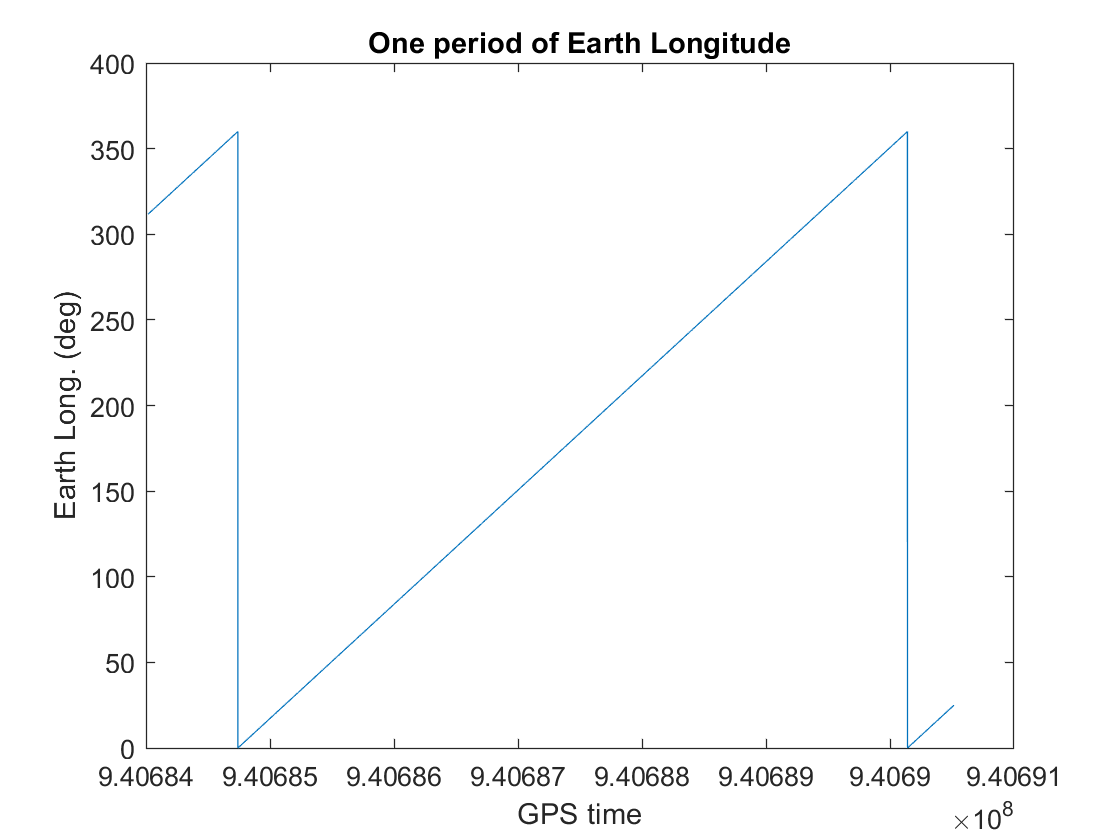

subplot(1,1,1)
plot(time(40000:105000),earthlong(40000:105000))
title('One period of Earth Longitude')
xlabel('GPS time')
ylabel('Earth Long. (deg)')

Using the graph, one period for Earth longitude is about $\Delta t=6400$, from t = 940684600 to t = 940691000. 

So graphing a few histograms of counts within this interval will show the progression of the background distribution:

- t = 9.40685 to t = 9.40686 ($\cdot {10}^8$)

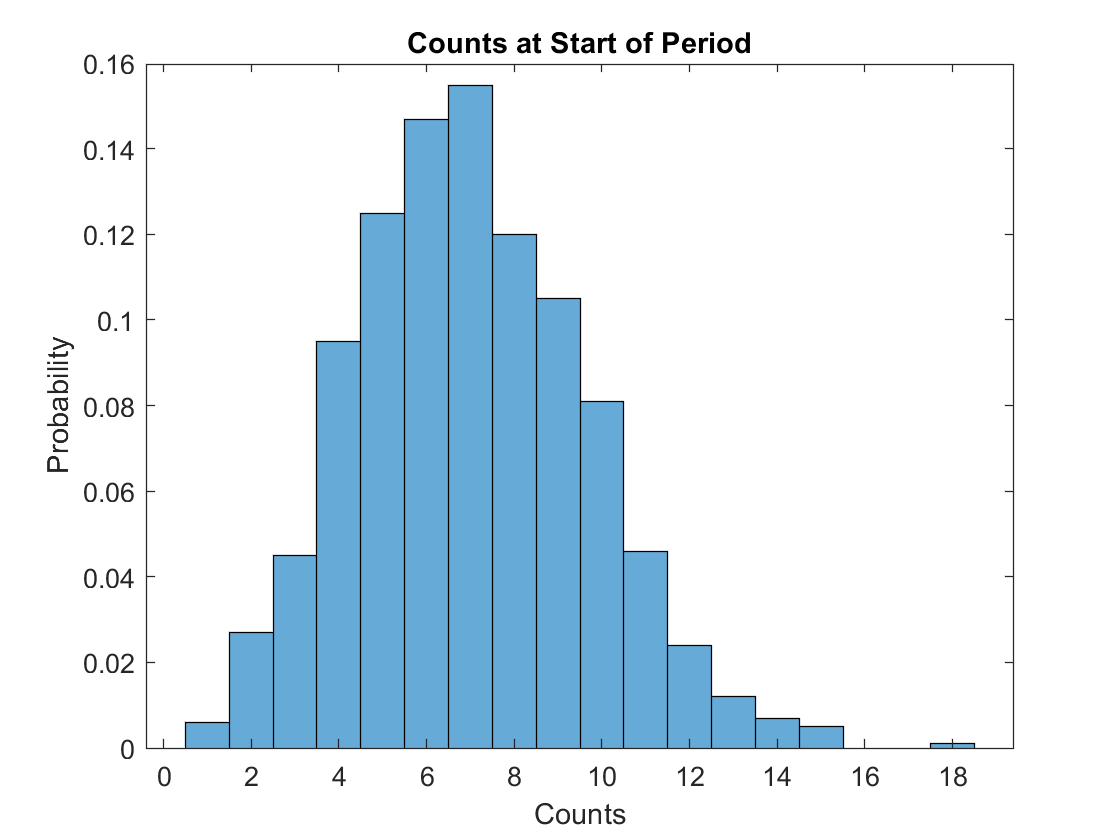

n = 940685000 - time(1);
m = 940686000 - time(1);
subplot(1,1,1)
histogram(counts(n:m),'Normalization','pdf')
title('Counts at Start of Period')
xlabel('Counts')
ylabel('Probability')

lambdast = mean(counts(n:m))

lambdast =    7.015984015984016


and

- t = 9.40689 to t = 9.40690

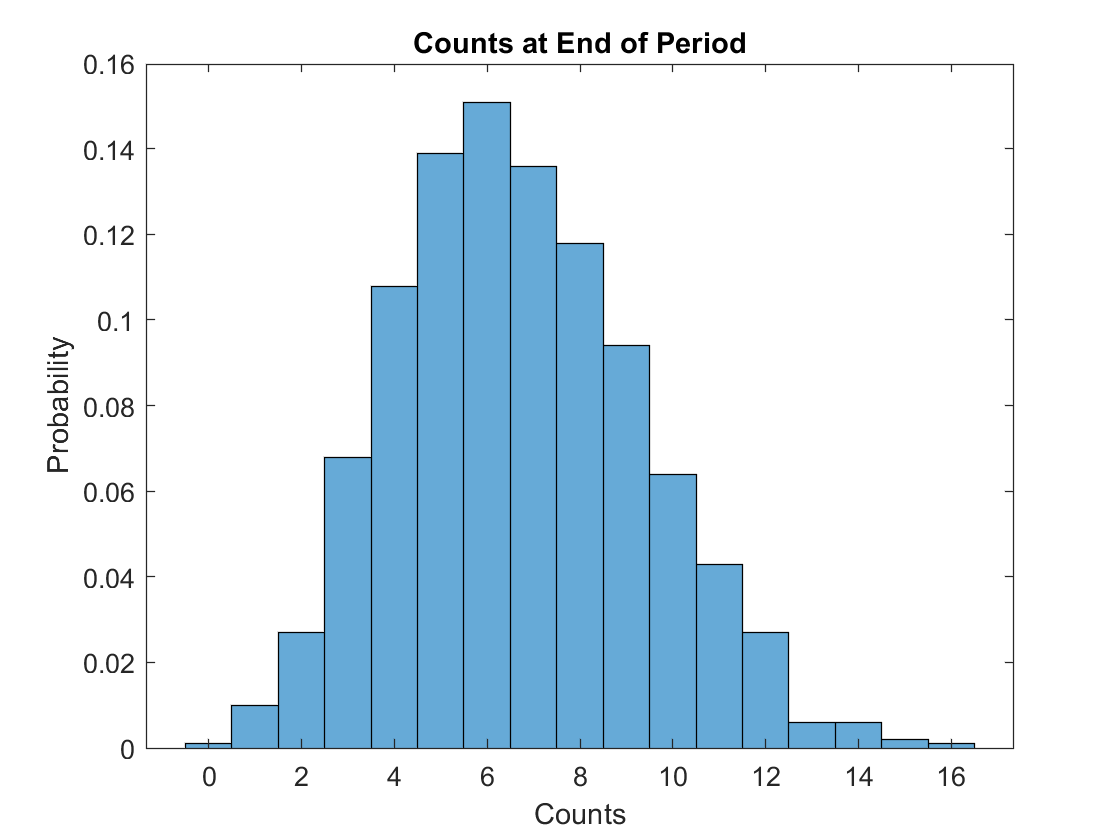

p = 940689000 - time(1);
q = 940690000 - time(1);
subplot(1,1,1)
histogram(counts(p:q),'Normalization','pdf')
title('Counts at End of Period')
xlabel('Counts')
ylabel('Probability')

lambdaen = mean(counts(p:q))

lambdaen =    6.681318681318682


As I predicted, the mean decreases throughout the period. 

*Comparing the histograms to a Poisson distribution:*

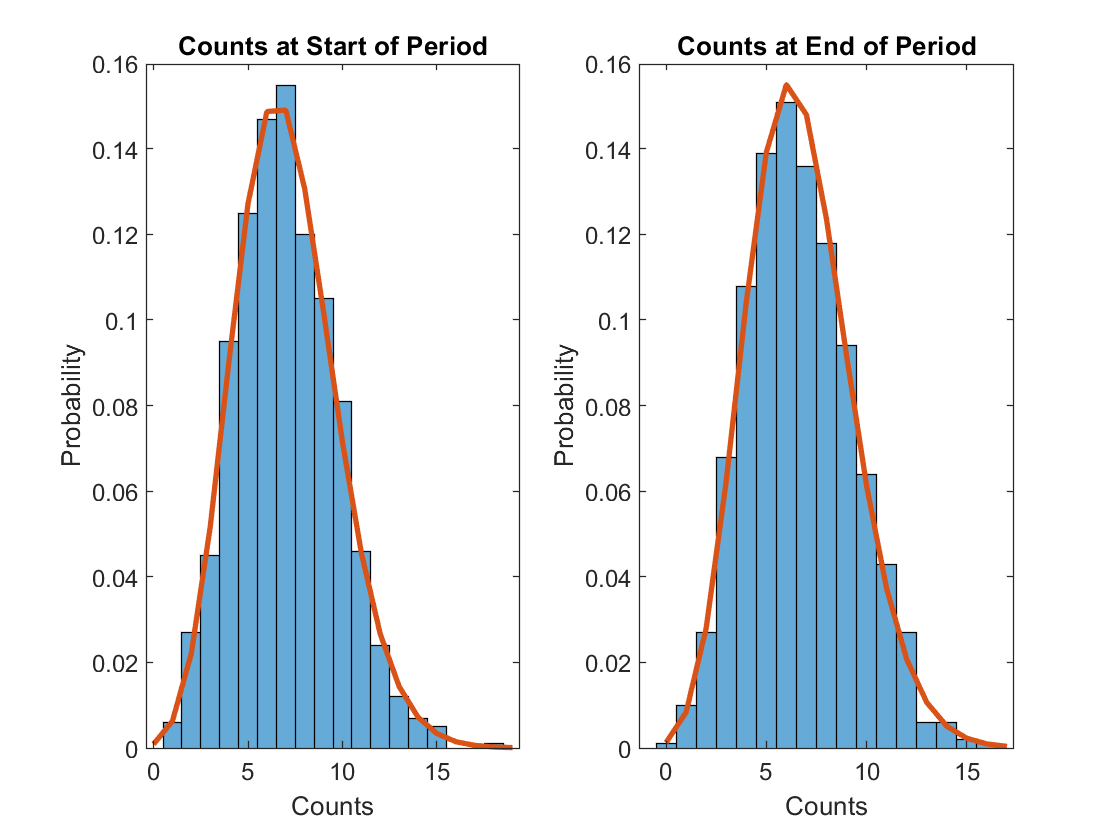

subplot(1,2,1)
histogram(counts(n:m),'Normalization','pdf')
hold on
title('Counts at Start of Period')
xlabel('Counts')
ylabel('Probability')
pds = makedist('Poisson','lambda',lambdast);
plot(0:19,pdf(pds,0:19),'LineWidth',2)
hold off

subplot(1,2,2)
histogram(counts(p:q),'Normalization','pdf')
hold on
title('Counts at End of Period')
xlabel('Counts')
ylabel('Probability')
pde = makedist('Poisson','lambda',lambdaen);
plot(0:17,pdf(pde,0:17),'LineWidth',2)
hold off

That's a pretty decent approximation. 

To properly create a time-dependent background distribution, I need to know when in the period the time is, and adjust the mean accordingly, so for some time t, the background distribution is the Poisson distribution with lambda = average of the counts of the corresponding section of the period.

### 4) '5-sigma' Threshold for a 100 ms $\gamma$-Ray Beam at Different Times

I have the pdfs for the times I mentioned in (3), so at t = 940685500 and t = 940689500, I need to find the 5 sigma threshold for a 100 ms gamma ray beam. 

- At t = 940685500, my background is a Poisson distribution with $\lambda =7\ldotp 0160$. 

sigma = 5;
background = makedist('Poisson','lambda',lambdast);
prob = normcdf(5);
threshold1 = icdf(background,prob)

threshold1 =     24


- At t = 940689500, my background is a Poisson distribution with $\lambda =6\ldotp 6813$. 

sigma = 5;
background = makedist('Poisson','lambda',lambdaen);
prob = normcdf(5);
threshold2 = icdf(background,prob)

threshold2 =     23


The threshold decreases along with the mean counts, so later in the longitude period, the sensitivity threshold is lower. 

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.

### 1) Dowloading the Data

images.h5 is a stack of 10 square, 200x200 pixel images. 

h5disp('images.h5')

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


*Generating images...*

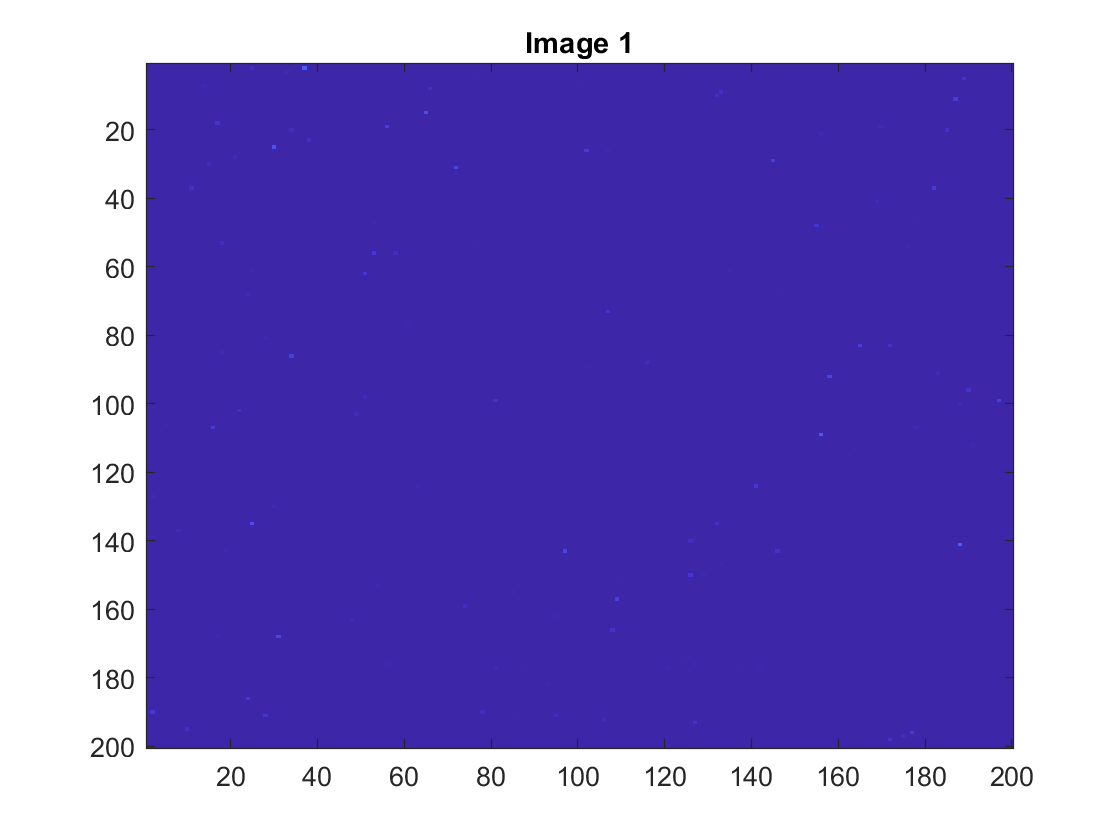

image1 = h5read('images.h5','/image1');
subplot(1,1,1)
image(image1)
title('Image 1')

imagestack = h5read('images.h5','/imagestack');

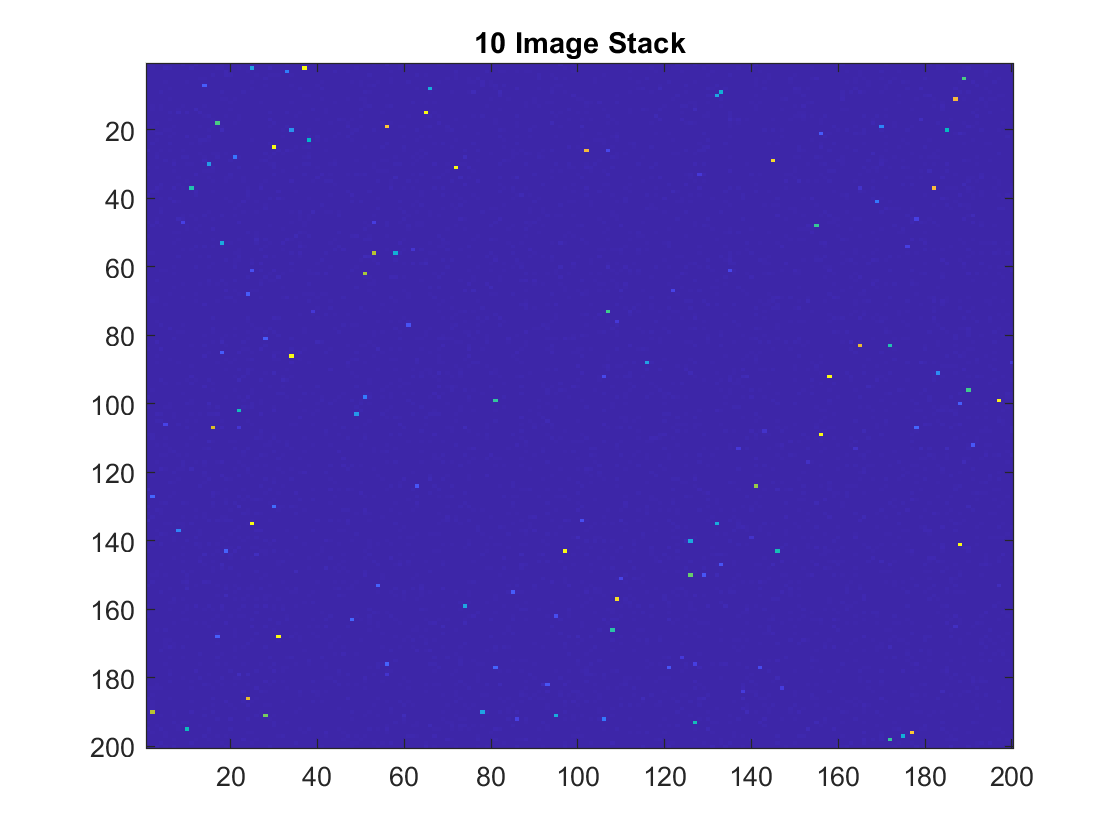

stack = zeros(200,200);

for k = 1:200
    for j = 1:200
        stack(k,j) = sum(imagestack(:,k,j));
    end
end

image(stack)
title('10 Image Stack')

### 2) Data Exploration

*Plotting pixel brightness:*

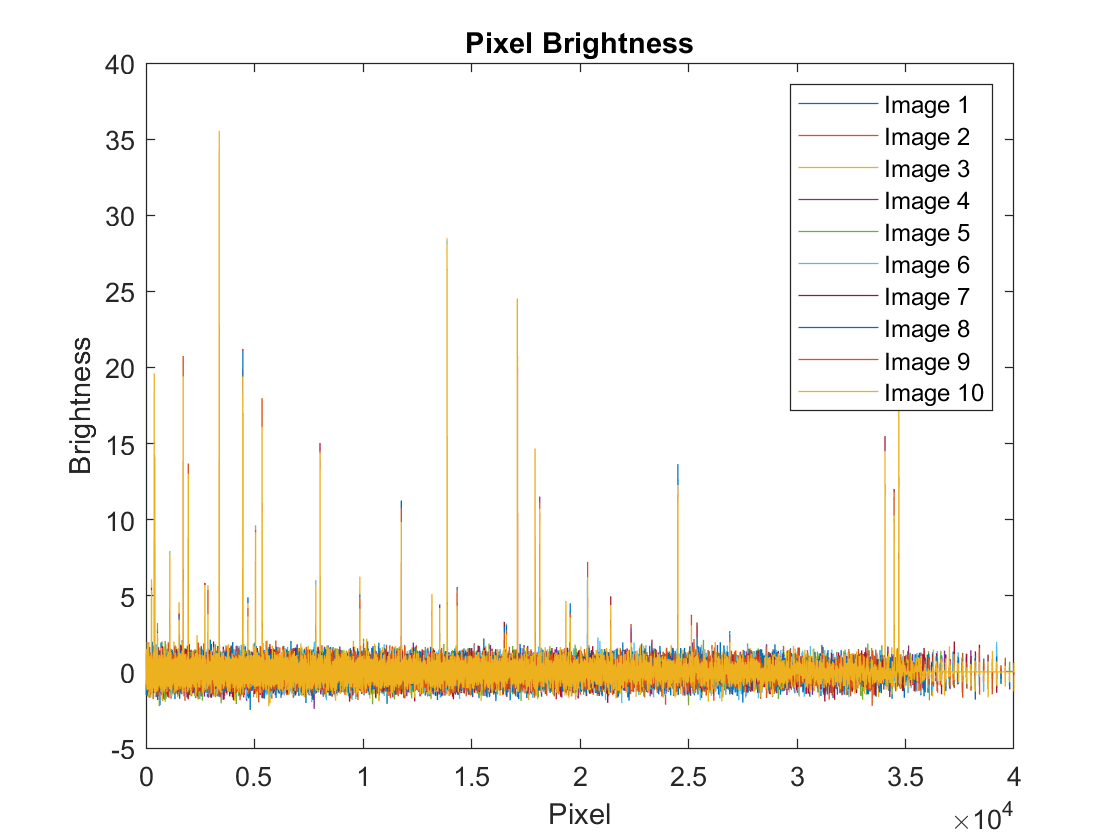

brightness = zeros(10,40000);

for b = 1:10
    for i = 1:200
        for h = 1:200
            brightness(b,i*h) = imagestack(b,i,h);
        end
    end
end

x = 1:40000;
brightness1 = brightness(1,:);
plot(x,brightness1)
hold on
for i = 2:10
    plot(x,brightness(i,:))
end
hold off

legend('Image 1','Image 2','Image 3','Image 4','Image 5','Image 6', ...
    'Image 7', 'Image 8', 'Image 9', 'Image 10')
title('Pixel Brightness')
xlabel('Pixel')
ylabel('Brightness')

The plot shows the brightness of every pixel, in every image in the stack. I manipulated the array so that I could plot every pixel along the same axis.

Looking at this plot, the background is the staticy line near zero, while the stars are represented by the peaks of brightness. 

*An alternative graphic:*

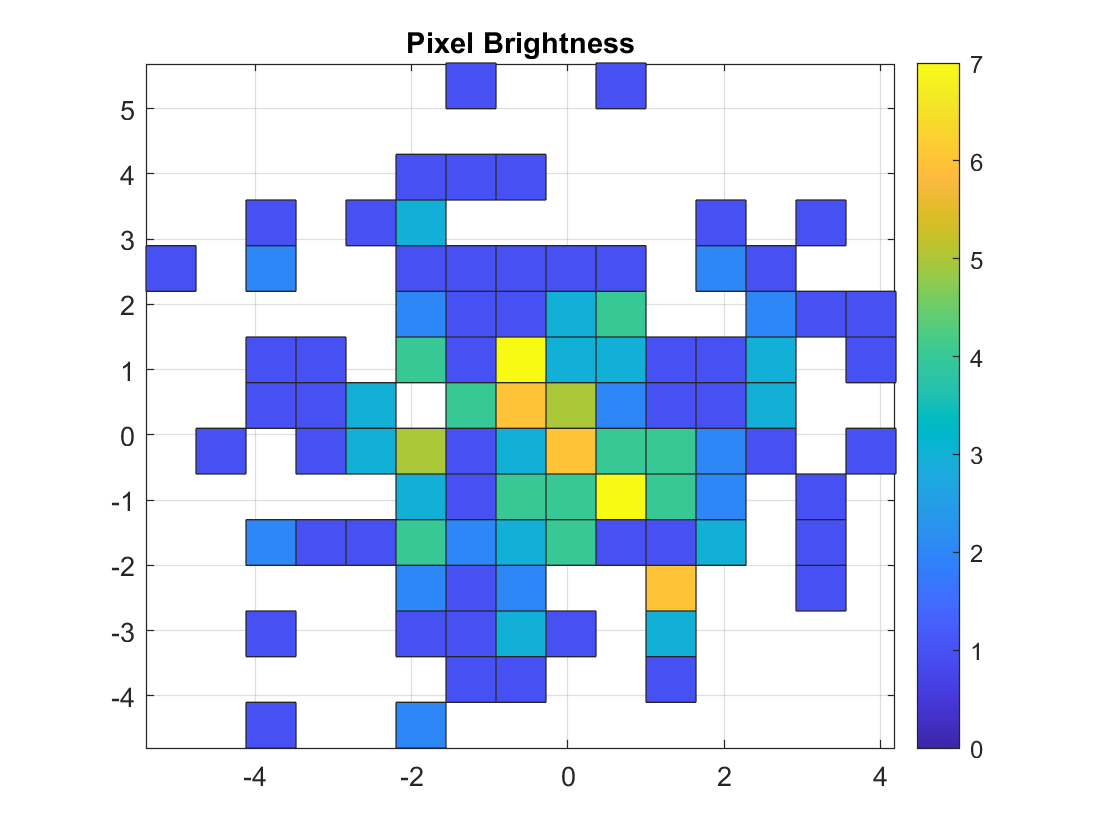

X = stack(1,:);
y = stack(:,1);
Y = zeros(1,200);

for w = 1:200
    Y(1,w) = y(w,1);
end

histogram2(X,Y,[15,15],'DisplayStyle','tile')
colorbar
title('Pixel Brightness')

Honestly, this graphic (despite looking pretty cool) isn't terribly useful. The plot above this histogram has more specific information about location of stars and background distribution, while this graph more generally shows that most of the signals are located around 0 brightness (something I could also see in my line plot).

*Subtracting the last image from the first image:*

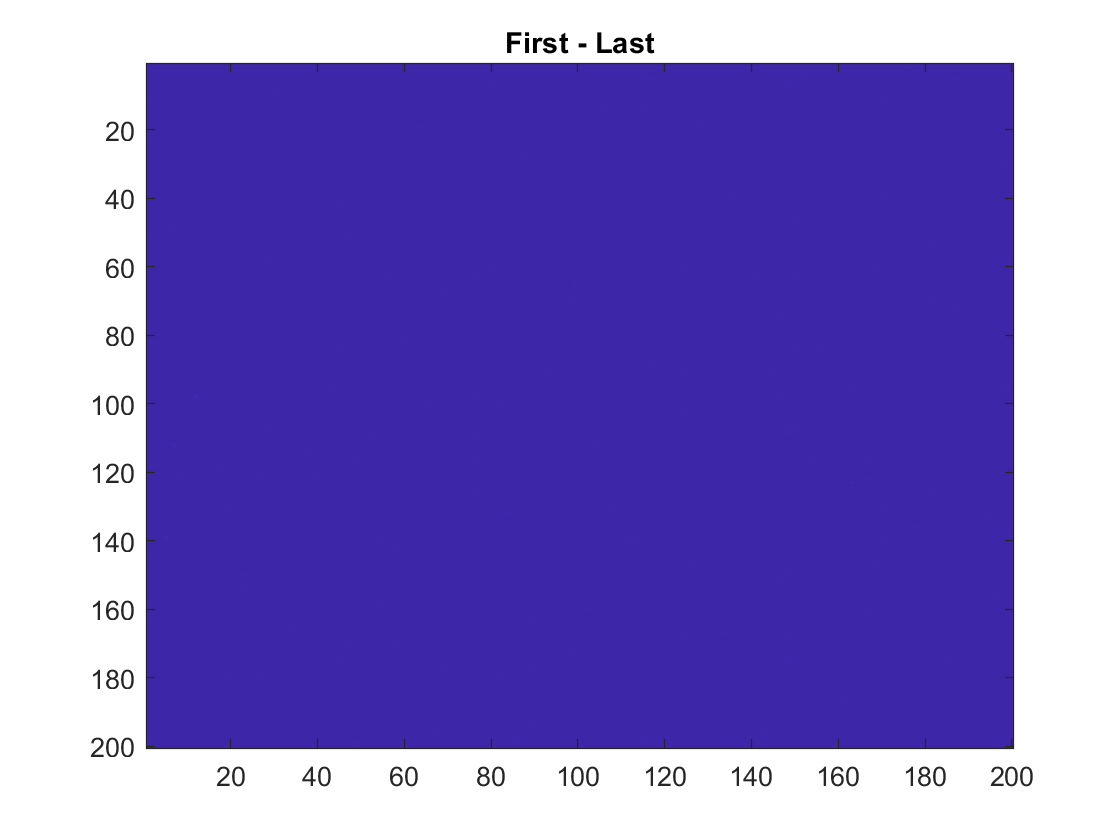

firstlast = zeros(200,200);

for m = 1:200
    for n = 1:200
        firstlast(m,n) = imagestack(1,m,n) - imagestack(10,m,n);
    end
end
image(firstlast)
title('First - Last')

If no stars moved or changed brightness over the 10 images, this would be a perfect representation of the background. Unfortunately, I currently don't know that that's the case, so it remains simply a pretty blue rectangle until I can confirm. 

*First - Last image in a line plot:*

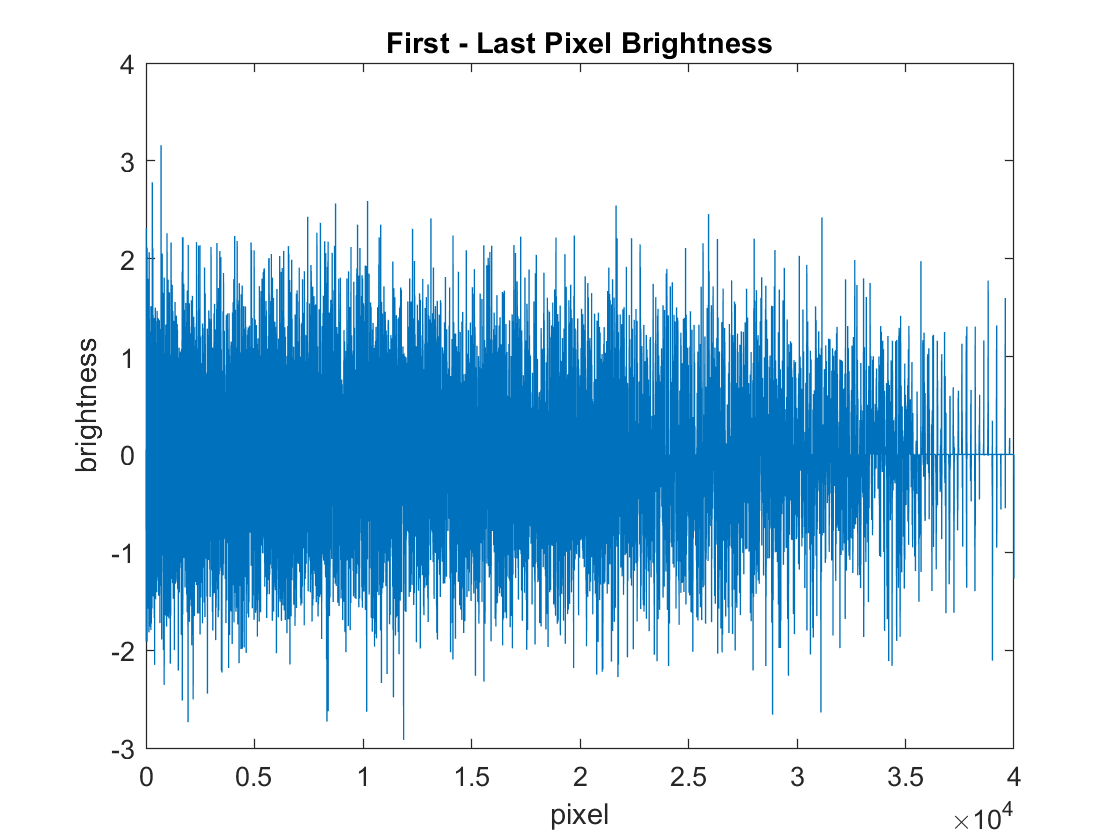

diff = zeros(1,40000);

for i = 1:200
    for h = 1:200
        diff(1,i*h) = firstlast(i,h);
    end
end

subplot(1,1,1)
plot(x,diff)
title('First - Last Pixel Brightness')
xlabel('pixel')
ylabel('brightness')

This shows a plot of the differences in pixel brightness between the first and last images (essentially a line plot of the previous image). Note that the differences don't surpass 4 on the brightness scale, which is small relative to star brightness (up to 35). 

### 3) Signal Scavenger Hunt

*I've chosen to look for a transient. *

A transient is something like a super nova that appears in one image but doesn't appear in another image, so I'm looking for a change in brightness between frames. 

My process for finding any transients present in the image stack is mostly brute force: calculate the changes between each pair of images (1 and 2 through 8 and 9) and find the maximum changes in brightness. From there, I'll consider each change on a case-by-case basis with more detailed plots and analysis. 

*Finding the maximum change between frames:*

changes = zeros(9,40000);

for r = 1:9
    changes(r,:) = abs(brightness(r,:) - brightness(r+1,:));
end

Here is the list of maximum changes for each pair of images in the stack:

onetwo = max(changes(1,:))

onetwo =    2.946583646109048


twothree = max(changes(2,:))

twothree =    3.188794937152031


threefour = max(changes(3,:))

threefour =    4.168097285409303


fourfive = max(changes(4,:))

fourfive =    2.987294594121865


fivesix = max(changes(5,:))

fivesix =    3.046083854691287


sixseven = max(changes(6,:))

sixseven =    4.070322412287277


seveneight = max(changes(7,:))

seveneight =    3.298004749645902


eightnine = max(changes(8,:))

eightnine =    3.286910702284874


nineten = max(changes(9,:))

nineten =    3.106036279799264


Most are in a range similar to the values in the plot of differences between the first and last images that I made in section (2), but I'll consider the 3-4 and 6-7 changes more closely.

*Closer examination:*

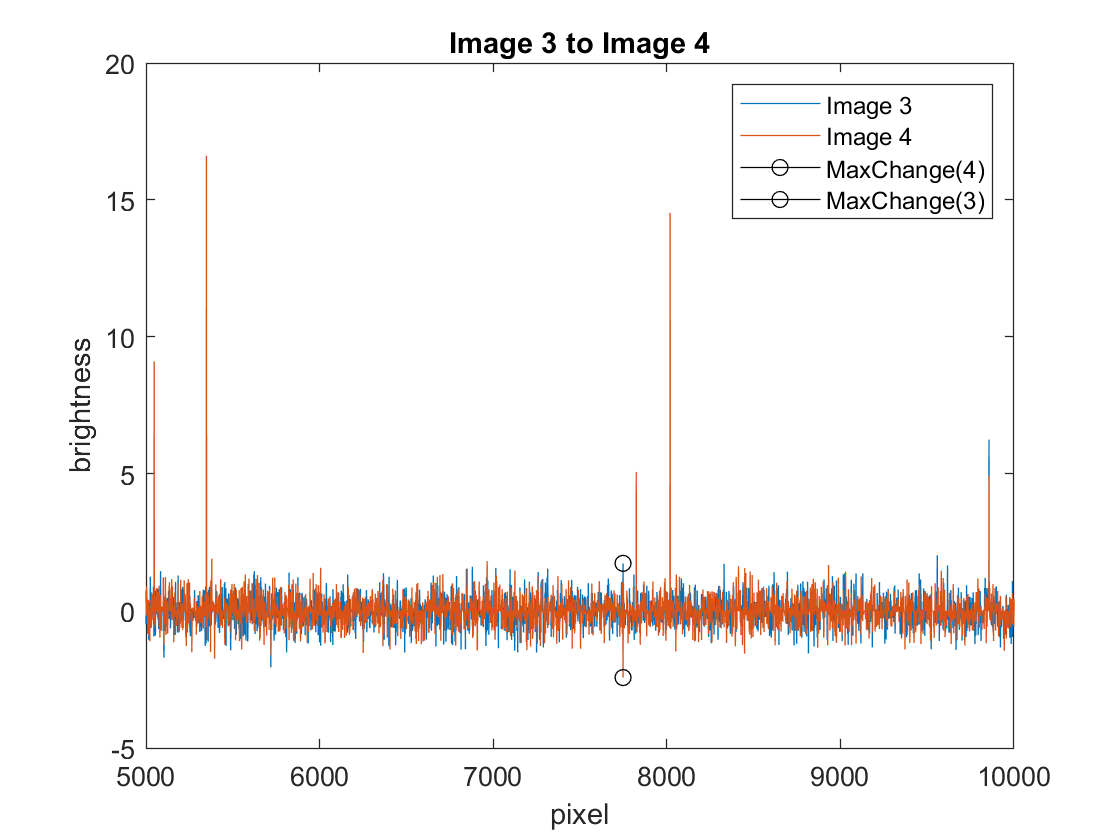

x = 1:40000;
plot(x,brightness(3,:))
hold on
plot(x,brightness(4,:))
xlim([0.5*10^4,10000])
title('Image 3 to Image 4')
xlabel('pixel')
ylabel('brightness')

[M,I] = max(changes(3,:));

plot(I,brightness(4,I),'-o','Color','black')
plot(I,brightness(3,I),'-o','Color','black')
legend('Image 3','Image 4','MaxChange(4)','MaxChange(3)')
hold off

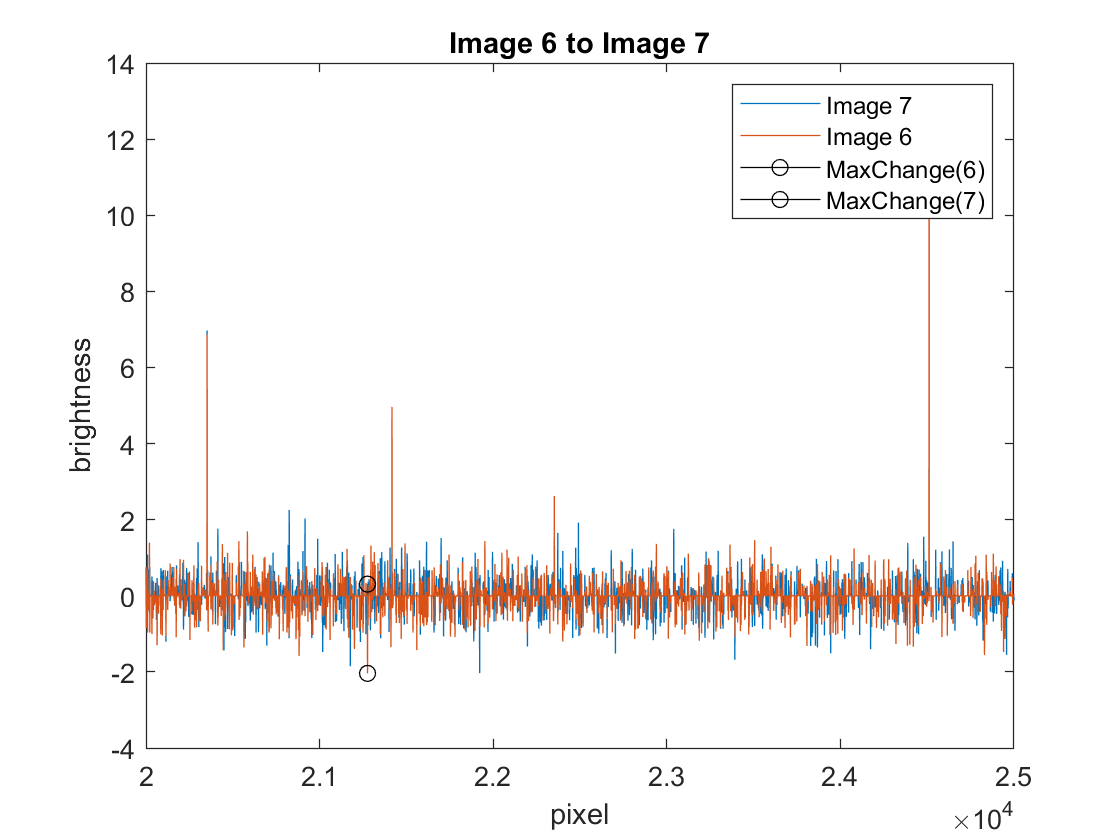

[N,J] = max(changes(7,:));
plot(x,brightness(6,:))
hold on
plot(x,brightness(7,:))
xlim([20000,25000])
title('Image 6 to Image 7')
xlabel('pixel')
ylabel('brightness')
plot(J,brightness(6,J),'-o','Color','black')
plot(J,brightness(7,J),'-o','Color','black')
legend('Image 7','Image 6','MaxChange(6)','MaxChange(7)')
hold off

The black circles denote the values of the two images at the point where the change was greatest. 

Inspecting these graphs, it doesn't seem like either is likely to be a transient unless it is very dim; both are close to the background static region. 

In conclusion, there are no transients in this stack of images. 

### 4) Different pdf() for the Same Data?

The background is decided based on what we're searching for. In this problem, the background doesn't follow a well-defined distribution, like the Poisson in problem 1. Instead, each individual defines their background based on the criteria they are considering. For me, that would be the potential transients, while for one of my lab partners, the criteria would be faint stars. 